clc; close all; clear;

Testing the speed of the ball with diffrent width og rails.

This is a aprocktimation modell, the track ruller is best!!!!!!!!!!

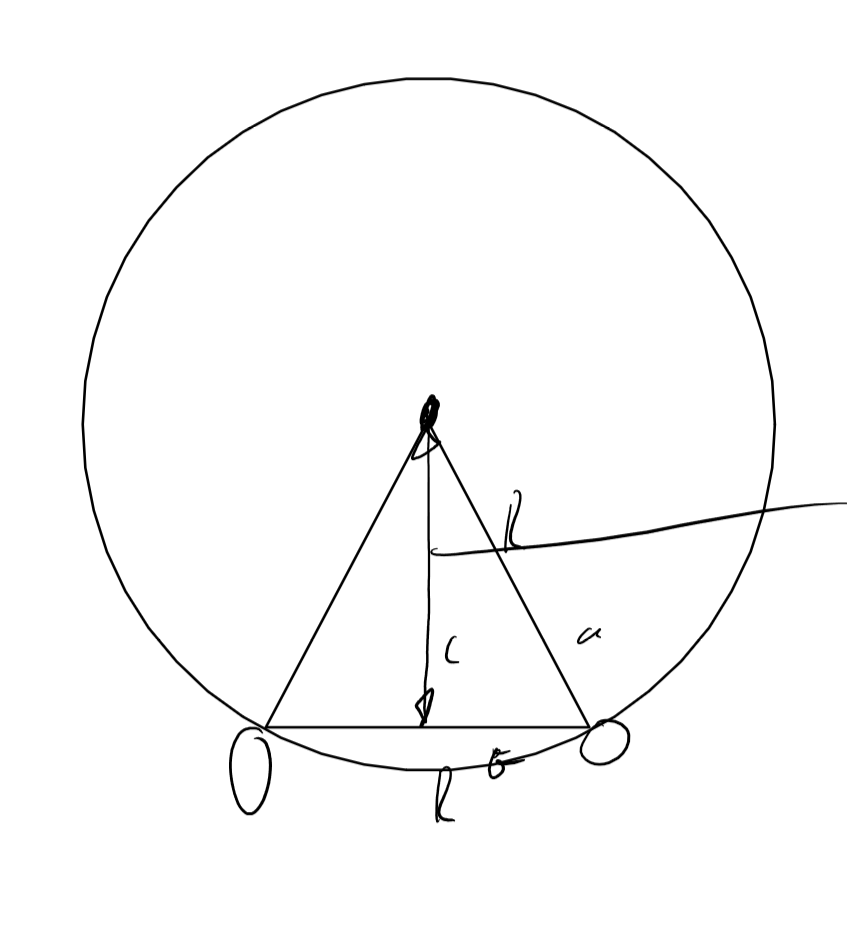

The circel represents the table teni ball, the triangel represents the ball on the rails

Omega_test = 0.5 ;% rad/s
g = 9.81*10^3; % mm/s^2
Angel_down_hill = (0:0.5:15); % deg
rad_down_hill = deg2rad(Angel_down_hill);

R_ball = 40.1/2;
% rail width
d_beam_30 = 30 ;% mm
d_beam_20 = 20; % mm
d_beam_17 = 16.667; % mm
d_beam_10 = 10 ;% mm
d_beam_0  =  0; % mm


% Higth from center mass to rail
c_height_30 = sqrt(R_ball^2-(d_beam_30/2)^2);
c_height_20 = sqrt(R_ball^2-(d_beam_20/2)^2);
c_height_17 = sqrt(R_ball^2-(d_beam_17/2)^2);
c_height_10 = sqrt(R_ball^2-(d_beam_10/2)^2);
c_height_0 = sqrt(R_ball^2-(d_beam_0/2)^2);


Finding velocity of center mass based on conservation of energy.

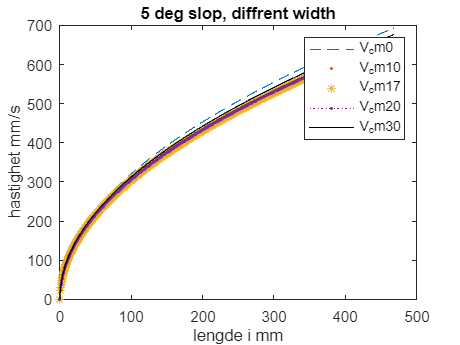

length_of_beam =(0:1/2:468.8);

heigth_0 =length_of_beam.*sin(0);
heigth_5 = length_of_beam.*sin(deg2rad(5));
heigth_10 = length_of_beam.*sin(deg2rad(10));
heigth_15 = length_of_beam.*sin(deg2rad(15));


% first with a 5 degree slope
V_cm_0_1 =  sqrt((g*heigth_5*6)/5);
V_cm_10_1 = sqrt((g*heigth_5)/(1/2+(1/3*R_ball^2*1/(R_ball^2-c_height_10^2/4))));
V_cm_17_1 = sqrt((g*heigth_5)/(1/2+(1/3*R_ball^2*1/(R_ball^2-c_height_17^2/4))));
V_cm_20_1 = sqrt((g*heigth_5)/(1/2+(1/3*R_ball^2*1/(R_ball^2-c_height_20^2/4))));
V_cm_30_1 = sqrt((g*heigth_5)/(1/2+(1/3*R_ball^2*1/(R_ball^2-c_height_30^2/4))));


plot(length_of_beam,V_cm_0_1, '--')
hold on
plot(length_of_beam,V_cm_10_1, '.')
hold on
plot(length_of_beam,V_cm_17_1, '*')
hold on
plot(length_of_beam,V_cm_20_1, ':.')
hold on
plot(length_of_beam,V_cm_30_1, 'k')
xlabel('lengde i mm')
ylabel('hastighet mm/s')
title('5 deg slop, diffrent width')
legend('V_cm0','V_cm10','V_cm17', 'V_cm20','V_cm30')
hold off

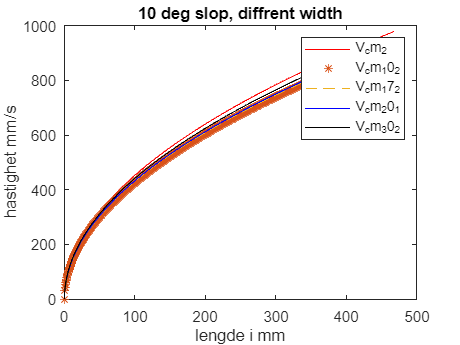


%first with a 10 degree slope
V_cm_0_2 = sqrt((g*heigth_10*6)/5);;
V_cm_10_2 = sqrt((g*heigth_10)/(1/2+(1/3*R_ball^2*1/(R_ball^2-c_height_10^2/4))));
V_cm_17_2 = sqrt((g*heigth_10)/(1/2+(1/3*R_ball^2*1/(R_ball^2-c_height_17^2/4))));
V_cm_20_2 = sqrt((g*heigth_10)/(1/2+(1/3*R_ball^2*1/(R_ball^2-c_height_20^2/4))));
V_cm_30_2 = sqrt((g*heigth_10)/(1/2+(1/3*R_ball^2*1/(R_ball^2-c_height_30^2/4))));

plot(length_of_beam,V_cm_0_2, 'r')
hold on
plot(length_of_beam,V_cm_10_2, '*')
hold on
plot(length_of_beam,V_cm_17_2, '--')
hold on
plot(length_of_beam,V_cm_20_2, 'b')
hold on
plot(length_of_beam,V_cm_30_2, 'k')
hold on

xlabel('lengde i mm')
ylabel('hastighet mm/s')
title('10 deg slop, diffrent width')
legend('V_cm_0_2','V_cm_10_2','V_cm_17_2', 'V_cm_20_1','V_cm_30_2')

hold off

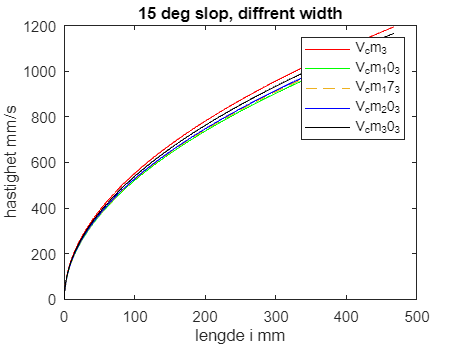


%first with a 15 degree slope
V_cm_0_3 = sqrt((g*heigth_15*6)/5);;
V_cm_10_3 = sqrt((g*heigth_15)/(1/2+(1/3*R_ball^2*1/(R_ball^2-c_height_10^2/4))));
V_cm_17_3 = sqrt((g*heigth_15)/(1/2+(1/3*R_ball^2*1/(R_ball^2-c_height_17^2/4))));
V_cm_20_3 = sqrt((g*heigth_15)/(1/2+(1/3*R_ball^2*1/(R_ball^2-c_height_20^2/4))));
V_cm_30_3 = sqrt((g*heigth_15)/(1/2+(1/3*R_ball^2*1/(R_ball^2-c_height_30^2/4))));

plot(length_of_beam,V_cm_0_3, 'r')
hold on
plot(length_of_beam,V_cm_10_3, 'g')
hold on
plot(length_of_beam,V_cm_17_3, '--')
hold on
plot(length_of_beam,V_cm_20_3, 'b')
hold on
plot(length_of_beam,V_cm_30_3, 'k')
hold on

xlabel('lengde i mm')
ylabel('hastighet mm/s')
title('15 deg slop, diffrent width')
legend('V_cm_0_3','V_cm_10_3','V_cm_17_3', 'V_cm_20_3','V_cm_30_3')
hold off




% Data fra måling
time = readtable("time.xlsx");

Error using readtable
Unable to find or open 'time.xlsx'. Check the path and filename or file permissions.

time1 = time(:,1);
%time1 = rows2vars(time);
time_2 = time1.Var1';
%time2 = time_.OriginalVariableNames;
% time = struct(ball_5Deg.signals);
% time = tid2(1);
% time = tid3.values';




posisjon = readtable("posisjon.xlsx");
%posisjon = posisjon1(1,:);
posisjon1 = rows2vars(posisjon);
X_pos= abs(posisjon1.Var1')
plot(time_2,X_pos, '.');

% %%% funket ikke Under 
% x_pos_change = X_pos(65:98);
% time_2_change = time_2(65:98);
% % numerisk derivasjon for hastighet
% %diff = diff(posisjon2);
% n = length(x_pos_change);
% dy = diff(x_pos_change);
% dx = diff(time_2_change);
% 
% dy_dx = dy./dx;
% dy_dx(n) =dy_dx(n-1);
% plot(time_2_change,dy_dx,'-')
% hold on
% %plot(length_of_beam,V_cm_17_2, '--')
% 2:n
% 
% for i = 2:n-1
%     v(i) = (x_pos_change(i+1)-x_pos_change(i-1))/(time_2_change(i+1)-time_2_change(i-1));
%     Speed =  [v(i)];
% end
% disp(Speed)
% plot(time_2_change,Speed)

%%%% funket ikke over

length_beam =(0:1:478);

for i = 1:length(length_beam)
    tid(i) = (i)/(sqrt((g*i.*sin(deg2rad(5)))/(1/2+1/(1-(d_beam_17^2)/(4*R_ball^2)))));

end
% disp(Speed)
% plot(length_of_beam,V_cm_17_1, '--')